% MATLAB Code to Determine Warburg Coefficient
% Load the LT-Spice exported CSV file
filename = 'Randle circuit 1 alt[2].csv';
data = readtable(filename, 'Delimiter', '\t');


% Extract frequency and combined magnitude-phase data
frequency = data{:, 'Freq_'}; % Frequency column
combined_data = data{:, 'V_input__I_V1_'}; % Combined magnitude-phase column

% Parse magnitude (in dB) and phase (in degrees) from combined data
num_entries = length(combined_data);
magnitude_db = zeros(num_entries, 1);
phase_deg = zeros(num_entries, 1);

for i = 1:num_entries
    % Extract values using regular expressions
    match = regexp(combined_data{i}, '\(([^dB]+)dB,([^°]+)°\)', 'tokens');
    magnitude_db(i) = str2double(match{1}{1}); % Magnitude in dB
    phase_deg(i) = str2double(match{1}{2}); % Phase in degrees
end

% Convert magnitude from dB to linear scale
magnitude_linear = 10.^(magnitude_db / 20);

% Calculate real and imaginary parts
real_part = magnitude_linear .* cosd(phase_deg);
imag_part = magnitude_linear .* sind(phase_deg);

% Focus on the low-frequency region (e.g., first 10% of data)
low_freq_indices = 1:floor(0.1 * num_entries);
freq_low = frequency(low_freq_indices);
real_low = real_part(low_freq_indices);
imag_low = imag_part(low_freq_indices);

% Fit the low-frequency impedance to determine the Warburg coefficient
omega_low = 2 * pi * freq_low; % Angular frequency
Z_low = sqrt(real_low.^2 + imag_low.^2); % Magnitude of impedance

% Linear fit to log(Z) vs. log(sqrt(omega)) to determine Warburg coefficient
sqrt_omega = sqrt(omega_low);
log_sqrt_omega = log(sqrt_omega);
log_Z_low = log(Z_low);

% Perform linear regression
p = polyfit(log_sqrt_omega, log_Z_low, 1);

% Warburg coefficient (sigma) is the exponent of the intercept
slope = p(1);
intercept = p(2);
sigma = exp(intercept); % Warburg coefficient

% Display the Warburg coefficient
disp(['Warburg Coefficient (σ): ', num2str(sigma)]);

Warburg Coefficient (σ): 1000.2236


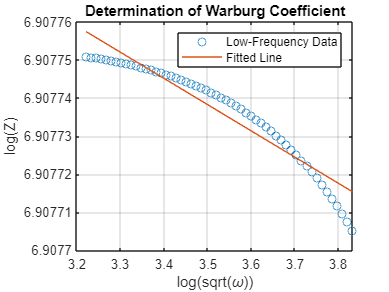


% Plot the low-frequency region with the fitted line
figure;
plot(log_sqrt_omega, log_Z_low, 'o', 'DisplayName', 'Low-Frequency Data');
hold on;
plot(log_sqrt_omega, polyval(p, log_sqrt_omega), '-', 'DisplayName', 'Fitted Line');
xlabel('log(sqrt(\omega))');
ylabel('log(Z)');
title('Determination of Warburg Coefficient');
legend;
grid on;